% This script explore the effect of changing some parameters on predicted
% mu_shift/NLL


## Set up

clear all; close all; clc

sub = 1;
ses = 1;

%% manage paths
currentDir = pwd;
exptDir = currentDir(1:regexp(pwd,'03analyses')-1); % project folder
addpath(genpath([exptDir '/02data'])); % data folder, necessary to run organize_data
addpath(genpath([exptDir '/03analyses/01analysesFunctions'])); % function folder
addpath('/Users/luhe/Documents/GitHub/bads') % add bads to path, to be changed later

%% organize data
data(sub, ses)= organize_data(sub, ses);

% set fixed & set-up parameters
model(sub, ses).expo_num_sim = 1e3; % number of simulation for exposure phase
model(sub, ses).expo_num_trial = 250; % number of *real* trials in exposure phase
model(sub, ses).num_runs = 100; %fit the model 100 times, each with a different initialization
model(sub, ses).num_bin = 100; % num bin to approximate mu_shift
model(sub, ses).thre_r2 = 0.95; %if R2<0.95, we use KDE

% define the grid for free parameters
model(sub, ses).paraID = {'\mu_{pre}','\sigma_{pre}','c_{pre}','\lambda','\sigma_{post}',...
    'c_{post}','p_{common}','\sigma_{soa}','\sigma_{c1}','\sigma_{c2}','alpha'};
model(sub, ses).numPara = length(model(sub, ses).paraID);


## Test sigma_C2

% default/suggested values of free parameters (for debugging cal_NLL_CI)
mu1 = 0.03; % s
sigma1 = 0.07; %s
c1 = 0.09;
lambda = 0.03;
sigma2 = 0.09;
c2 = 0.12;
p_common = 0.3;
sigma_soa  = 0.16;
sigma_c1 = 0.01;
sigma_c2s= 0.02:0.01:1;
alpha  = 0.01;

parfor ii = 1:numel(sigma_c2s)

    NLL(ii) = cal_nLL_CI(mu1, sigma1, c1, lambda,... % pretest free para
        sigma2, c2, ... % posttest free para
        p_common, sigma_soa, sigma_c1, sigma_c2s(ii), alpha, ... % recal simul para
        model, data); % fixed para, data

end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


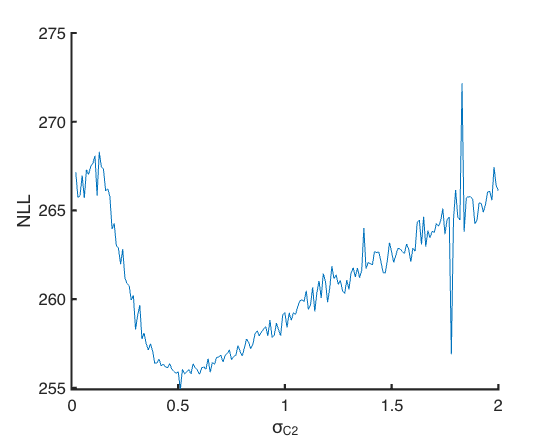


figure; hold on
set(gca, 'LineWidth', 2, 'FontSize', 15)
set(gcf, 'Position',[10 10 500 400])
plot(sigma_c2s, NLL)
xlabel('\sigma_{C2}')
ylabel('NLL')

## Test tradeoff between p_common and sigma_c2

% default/suggested values of free parameters (for debugging cal_NLL_CI)
mu1 = 0.03; % s
sigma1 = 0.07; %s
c1 = 0.09;
lambda = 0.03;
sigma2 = 0.09;
c2 = 0.12;
p_commons = 0.01:0.01:0.99;
sigma_soa  = 0.16;
sigma_c1 = 0.01;
sigma_c2s= 0.2:0.01:2;
alpha  = 0.01;

for ii = 1:numel(sigma_c2s)
    parfor jj = 1:numel(p_commons)
        NLL(ii,jj) = cal_nLL_CI(mu1, sigma1, c1, lambda,... % pretest free para
            sigma2, c2, ... % posttest free para
            p_commons(jj), sigma_soa, sigma_c1, sigma_c2s(ii), alpha, ... % recal simul para
            model, data); % fixed para, data
%         disp([ii, jj])
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


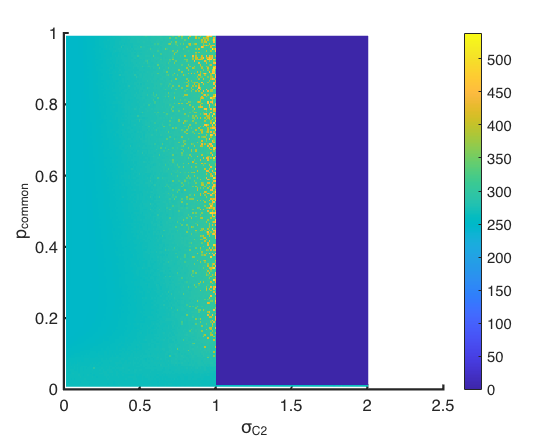


figure; hold on
set(gca, 'LineWidth', 2, 'FontSize', 15)
set(gcf, 'Position',[10 10 500 400])
imagesc(sigma_c2s, p_commons, NLL)
xlabel('\sigma_{C2}')
ylabel('p_{common}')
colorbar

## Test tradeoff between p_common and alpha

% default/suggested values of free parameters (for debugging cal_NLL_CI)
mu1 = 0.03; % s
sigma1 = 0.07; %s
c1 = 0.09;
lambda = 0.03;
sigma2 = 0.09;
c2 = 0.12;
p_commons = 0.01:0.01:0.99;
sigma_soa  = 0.16;
sigma_c1 = 0.01;
sigma_c2 = 0.05;
alphas  = 0.001:0.001:0.02;

for ii = 1:numel(alphas)
    parfor jj = 1:numel(p_commons)
        NLL2(ii,jj) = cal_nLL_CI(mu1, sigma1, c1, lambda,... % pretest free para
            sigma2, c2, ... % posttest free para
            p_commons(jj), sigma_soa, sigma_c1, sigma_c2, alphas(ii), ... % recal simul para
            model, data); % fixed para, data
    end
end

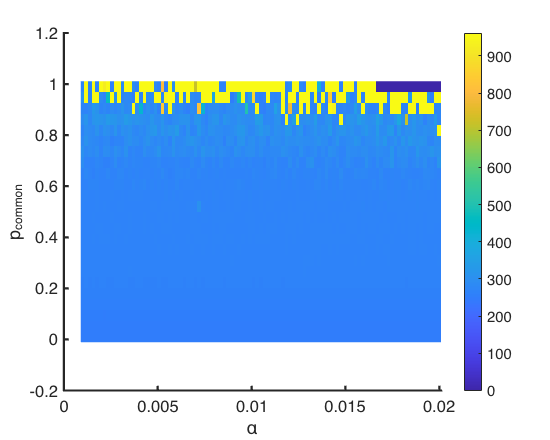


figure; hold on
set(gca, 'LineWidth', 2, 'FontSize', 15)
set(gcf, 'Position',[10 10 500 400])
imagesc(alphas, p_commons, NLL2)
xlabel('\alpha')
ylabel('p_{common}')
colorbar